# Analisis del pipeline para simulacion reproducible de tejido hepatico 

Evaluación comparativa de QUS por simulaciones (Benchmark):

- **v1: Implementar simulaciones de medios homogéneos variando primero un parámetro y luego varios parámetros.**

- v2: ImpIementar simulaciones con inclusiones: variación de un parámetro manteniendo los demás constantes y variación conjunta de varios parámetros.

- v3: Implementar medios por capas y geometrías simplificadas de tejidos.

- v4: Incorporar y comparar configuraciones de ultrasonido focalizado (F), onda plana (PW), compounding de ondas planas (PWC) y apertura sintética de transmisión (STA), según corresponda.

Que mejorar en GUI:

- Simulacion en cola, osea tener la opcion para que el script final en .mat o .sh mantenga antes del for todos los valores de variable que cambiara a lo largo del experimento, en la gui debe verse como sera la cola de esos resultados**. La intención sera comparar varios objetivos contra una referencia final.**

- **En la cola**, cada vez que se agregue ese nuevo parametro o se cambie (en ejecucion en la terminal), debe aparecer como se esta colocando en cola los experimentos de una misma seccion **(ya sea medio acustico, transductor emisor o sensor), **ya que de ese modo el vector que genera los experimentos por grupo sabra que grupo es el correspondiente al generar el .m.

Simulacion:

*"Implementar en k-Wave una primera simulación reproducible de un modelo simplificado de tejido hepático que permita estudiar el efecto de modificar un parámetro acústico".*

Tres casos de uso:

-  el **original** (mantener todo fijo y solo variar atenuacion y que salga en cola), 

- uno de **tejido hepatico sano** y otro de **fibroso** manteniendo constante los demas y que igual aparesca el cambio en la cola en este caso de diferentes secciones.

El hecho de cambio de parametros variables en diferentes secciones o que solo sea de un parametro variable de una seccion tiene que identificarlo la propia logica del codigo y debe aparecer en la parte de **ejecucion**:

- **(i) **Si solo es **un valor **el que quiero ejecutar un grupo 

               seccion x: [ valor ref ] (aqui solo ejecuto un grupo de experimentos

- **(ii) **Si solo es **una** de **seccion** debe aparecer la **cola** de: 

                seccion x: [ valores cambiados, valor_ref ]

- **(iii) **Si es en **varias secciones** debe aparecer:

                 seccion x: [ valores cambiados, valor ref ], 

                 seccion y: [ valores cambiados, valor ref ],

                 ...

                 seccion n: [valores cambiados, valor ref],

*Nota: le llamo colas pero en realidad son estructuras tal y cual esta en el codigo del .m*

Para implementar la logica que permita esto, debe pulsarse el boton "**set"** cuando se quiera setear una de estas variables en la cola y colocar "**save**" para que se guarde la cola de experimentos para un valor, una seccion o varias secciones en archivo .m y .sh.

- Inicialmente **open config** esta destinado a abrir la cola de grupos, de las cuales se realiaran el experimento y permitira visualizar como estuvo configurado en la seccion de **ejecucion**:

- Asimismo para abrir una configuracion anterior y modificar parametros de esa configuracion, mas a futuro se generara la opcion para que se pueda cambiar esa configuracion en la misma cola o de forma manual.

Cuando se guarde este archivo con el .m y .sh debe guardarse como una simulacion que al abrise con open config diferentes de estas configuraciones debe aparecer su nombre y distintas ventanas en **preview **(igualmente esta implementacion va al final ya que no es lo primordial aun), con esta logica (va igual al momento de realizar el setup al inicio):

- Si es solo un valor, debe aparecer: simulacion 1 y en ejecucion **(i)**

- Si es una seccion con una cola debe aparecer: simulacion 1 y en ejecucion **(ii) **

- Si es varias seccion con cola debe aparecer: simulacion 1, simulacion 2 ... simulacion n y en ejecucion (no importa cual preview se vea) **(iii)**

Abra dos implementaciones una en la cual pueda usar los recursos de la computadora (local) donde la barra de resultados si servira, ya que se mostraran los resultados de los experimentos por simulacion, (en otro momento el boton de visualizar todos los experimentos

### Preparacion del entorno:

En [Defining An Ultrasound Transducer](https://www.k-wave.org/documentation/example_us_defining_transducer.php), se especifica que:  

- Para reducir el gasto computacional, los calculos usan double (8 bytes), sin embargo mejor usaremos single (4 bytes), para ello hacemos: (`'DataCast','single').`

- Con parallax se puede: `'DataCast'` to `'gpuArray-single'`

clearvars %Borra las variables del Workspace
clc %Limpia la ventana de comandos.
%Activa una opción de compatibilidad para GPU NVIDIA CUDA mediante Parallel Computing Toolbox.
parallel.gpu.enableCUDAForwardCompatibility(true) 

%En MAC:
rng(23) %Fija la semilla del generador aleatorio (sirve para reproduciblidad).
addpath(genpath(pwd)) %Agrega al path de MATLAB la carpeta actual, pwd, y todas sus subcarpetas.

### **Configuración de salidas y referencias**

Define los grupos de simulaciones que se crearán y cuántas réplicas aleatorias tendrá cada uno.

Bucle externo: grupos de experimento

Bucle interno: realizaciones aleatorias dentro de cada grupo

Se puede variar:

- seed (por default 50000).

% Vector de valores usados para identificar cada grupo de simulaciones.

% El último valor, 0.524, se trata como referencia.
refValues = [0.55, 0.65, 0.8, 0.9, 0.524]; 

for ii = 1:length(refValues)
    % Recorre cada valor de refValues.
    % Todo el código dentro del bucle se ejecutará una vez por grupo.

    nRefs = 5;
    % Número inicial de realizaciones aleatorias por grupo.
    % Más adelante, el último grupo, la referencia, cambiará a 10.

    refSeedBase = 50000;
    % Semilla base para generar medios aleatorios reproducibles.
    % refSeed = 50000 + iRef, para volver reproducible cada grupo.

### Parámetros del medio

Estas propiedades se mantienen constantes para todas las simulaciones de este bloque, salvo que luego se cambien deliberadamente.

    %Parametros para medio homogeneo
    c0              = 1540; % velocidad del sonido [m/s]

At least one END is missing. The statement beginning here does not have a matching end.

Error using  / 
Matrix dimensions must agree.

    rho0            = 1000; % densidad del medio [kg/m^3]
    
    % atenuacion fija para este ejemplo aunq carpetas nombren diferente
    hom_alpha       = 0.53; % [dB/(MHz^y cm)] 

    % Desviación estándar relativa de la densidad.
    density_std     = 0.04; %se usa para crear variaciones aleatorias de densidad en el ruido gaussiano.

    %Nombre del experimento objetivo: convierte, por ejemplo, 0.55 en el texto "0p55".
    simuName = ['homogeneus_target_alpha', char(strrep(string(refValues(ii)), '.', 'p')), ...
        '_std', char(strrep(string(density_std), '.', 'p'))];

    %Tratamiento especial del último grupo: la última posición de refValues se 
    % considera la referencia, por lo que tendrá 10 realizaciones aleatorias, no 5.
    if (ii == length(refValues))
        nRefs = 10;
        simuName = ['homogeneus_ref_alpha', char(strrep(string(refValues(ii)), '.', 'p')), ...
        '_std', char(strrep(string(density_std), '.', 'p'))];
    end

    outputFolder = fullfile(pwd, simuName);
    
    if ~exist(outputFolder, 'dir')
        mkdir(outputFolder);
    end


### Parámetros de la fuente, malla y transductor

Definen cómo se emite el pulso y la geometría física del arreglo lineal.

Todos son parametros variables

    %Source parameters
    source_f0       = 6.66e6;   % source frequency [Hz] 6.66e6 Hz equivale a 6.66 MHz.
    source_amp      = 1e6;      % source pressure [Pa]
    source_cycles   = 3.5;      % number of toneburst cycles
    source_focus    = 4e-2;     % focal length [m]: profundidad focal de transmisión.
    element_pitch   = 0.3e-3;   % pitch [m]: distancia entre los centros de dos elementos consecutivos.
    element_width   = 0.25e-3;  % width [m]:  el espacio entre elementos.
    focal_number_Tx = 4;        % F-number de transmisión
    focal_number_Rx = 2;        % ayuda a decidir cuántos elementos físicos tendrá el arreglo que se simula.
    nLines          = 128;      % number of beams ( Número de scanlines, no equivale al número de elementos del transductor)

    % Transducer position
    base_translation = [-2.7e-2, 0];
    rotation         = 0;

    % Grid parameters: 
    % Luego los parametros de la malla
    grid_size_x     = 5.6e-2;   % [m]
    grid_size_y     = 4e-2;     % [m]


### Parámetros de computacion

Definen cómo k-Wave discretiza y ejecuta la simulación.

    %Computational parameters
    DATA_CAST       = 'gpuArray-single'; % set to 'single' or 'gpuArray-single'

    %Se usará después para calcular la resolucion dx (mayor ppw mas fina
    %simulacion pero mas coste computacional)
    ppw             = 6;                 % number of points per wavelength 

    % Este valor se utiliza para calcular el tiempo final de simulación (t)
    depth           = 5.5e-2;            % imaging depth [m]

    % Controla el tamaño del paso temporal de la simulación.
    cfl             = 0.3;               % CFL number: Courant-Friedrichs-Lewy
    PMLSize         = [41, 41];          % PML son 41 puntos de la malla (41*dx).
    
    % Controla si k-Wave muestra la simulación durante la ejecución o no.
    plotSimFlag     = false; % Es necesario para ejecutar muchas líneas y réplicas sin saturar MATLAB.

###  Configuración interna del pipeline focalizado 2D

- torneburst: puede ser variable posteriormente, fijo al inicio sera la unica que se hara en medio homogeneo

- `source_focus` o `focal_number_Tx: `puede ser variable posteriormente para PW, PWC, STA, se requiria otro pipeline para esas opciones posteriormente reemplazando

    %Grid ------------------------------------------------------------------------
    % Calculate the grid spacing based on the PPW and F0
    dx = c0 / (ppw * source_f0);   % [m]
    
    % Compute the size of the grid
    Nx = roundEven(grid_size_x / dx);
    Ny = roundEven(grid_size_y / dx);
    
    % Create the computational grid
    kgrid = kWaveGrid(Nx, dx, Ny, dx);
    
    % Create the time array
    t_end = depth * 2 / c0;        % [s]
    kgrid.makeTime(c0, cfl, t_end);

    % Source / array setup ------------------------------------------------------
    aperture_Rx = source_focus / focal_number_Rx;
    aperture_Tx = source_focus / focal_number_Tx;
    
    element_num_Tx = floor(aperture_Tx / element_pitch);
    element_num    = floor(aperture_Rx / element_pitch);
    
    amp_vector = source_amp * ones(element_num, 1);
    
    no_Tx_elements = floor((element_num - element_num_Tx) / 2);
    amp_vector(1:no_Tx_elements) = 0;
    amp_vector(end-no_Tx_elements+1:end) = 0;
    
    % Set indices for each element
    ids = (0:element_num-1) - (element_num-1)/2;
    
    % Set time delays for each element to focus at source_focus
    time_delays = -(sqrt((ids .* element_pitch).^2 + source_focus.^2) - source_focus) ./ c0;
    time_delays = time_delays - min(time_delays);
    
    % Create time-varying source signals: toneBurst crea el pulso de ultrasonido.
    source_sig = amp_vector .* toneBurst(1/kgrid.dt, source_f0, ...
        source_cycles, 'SignalOffset', round(time_delays / kgrid.dt));
    
    % Create empty kWaveArray: kWaveArray permite definir el transductor en metros,
    %  no en índices de malla.
    karray = kWaveArray('BLITolerance', 0.05, 'UpsamplingRate', 10);
    
    % Add rectangular elements
    for ind = 1:element_num
    
        % Set element y position
        y_pos = 0 - (element_num * element_pitch/2 - element_pitch/2) ...
            + (ind-1) * element_pitch;
    
        % Add element
        karray.addRectElement([0, y_pos], element_width/4, element_width, rotation);
    end

    %% Scanline coordinates --------------------------------------------------
    yCords = ((0:nLines-1) - (nLines-1)/2) * element_pitch;
    
    %Input options for k-Wave ------------------------------------------------
    input_args = {...
        'PMLInside', false, ...
        'PMLSize', PMLSize, ...
        'DataCast', DATA_CAST, ...
        'DataRecast', true, ...
        'PlotSim', plotSimFlag};

- `iRef  = réplica aleatoria dentro de ese grupo`

- `iLine = scanline dentro de una réplica`

`Se puede variar: `

- `kspace2d,3d, etc`

    % Reference simulation loop
    manifest = struct([]); %% Crea una estructura vacía para guardar metadatos

    for iRef = 1:nRefs
        refSeed = refSeedBase + iRef;
        rng(refSeed);
    
        fprintf('\n========================================\n');
        fprintf('Running homogeneous reference %d of %d\n', iRef, nRefs);
        fprintf('Seed: %d\n', refSeed);
        fprintf('========================================\n');
    
        % Homogeneous medium
        medium = makeHomogeneousDensityOnlyMedium( ...
            Nx, Ny, c0, rho0, density_std, hom_alpha);
    
        medium.alpha_power = 1;
        medium.alpha_mode = 'no_dispersion';
        medium.sound_speed_ref = 1540;
    
        % Optional: save a medium preview for each reference
        rx = kgrid.y;
        rz = kgrid.x - base_translation(1);
    
        figMedium = figure('Units', 'centimeters', 'Position', [5 5 25 10], ...
            'Visible', 'off');
    
        tiledlayout(1, 3)
    
        nexttile
        imagesc(100 * rx(1,:), 100 * rz(:,1), medium.sound_speed)
        xlabel('x [cm]')
        ylabel('z [cm]')
        title('Sound speed')
        c = colorbar;
        ylabel(c, 'm/s')
        axis image
    
        nexttile
        imagesc(100 * rx(1,:), 100 * rz(:,1), medium.density)
        xlabel('x [cm]')
        ylabel('z [cm]')
        title('Density')
        c = colorbar;
        ylabel(c, 'kg/m^3')
        axis image
    
        nexttile
        imagesc(100 * rx(1,:), 100 * rz(:,1), medium.alpha_coeff, [0.4 1.0])
        xlabel('x [cm]')
        ylabel('z [cm]')
        title('Absorption')
        c = colorbar;
        ylabel(c, 'dB/cm/MHz')
        axis image
    
        sgtitle(sprintf('Homogeneous reference %03d', iRef))
    
        savefig(figMedium, fullfile(outputFolder, ...
            sprintf('medium_homRef_%03d.fig', iRef)));
    
        saveas(figMedium, fullfile(outputFolder, ...
            sprintf('medium_homRef_%03d.png', iRef)));
    
        close(figMedium)

        % Allocate RF data: reserva de RF pre-beamforming
        rf_prebf = zeros(kgrid.Nt, element_num, nLines);

        %Beam loop
        for iLine = 1:nLines
            
            % Move the array
            translation = base_translation;
            translation(2) = yCords(iLine);
    
            karray.setArrayPosition(translation, rotation)
    
            % Assign binary source mask
            source.p_mask = karray.getArrayBinaryMask(kgrid);
    
            % Assign source signals
            source.p = karray.getDistributedSourceSignal(kgrid, source_sig);
    
            fprintf('Reference %d/%d | Line %d/%d\n', ...
                iRef, nRefs, iLine, nLines);
    
            %% Sensor
            sensor.mask = karray.getArrayBinaryMask(kgrid);
            sensor.directivity_size = 10 * kgrid.dx;
            sensor.directivity_angle = zeros(size(sensor.mask));
    
            %% Simulation 
            sensor_data = kspaceFirstOrder2D(kgrid, medium, source, sensor, ...
                input_args{:});
    
            % Combine sensor data into element RF channels
            combined_sensor_data = karray.combineSensorData(kgrid, sensor_data);
    
            % Store as [time, element, line]
            rf_prebf(:, :, iLine) = combined_sensor_data';
    
        end

Bucle de adquisición por 

Asimismo, `c0 = 1595 m/s` es la velocidad física usada en la simulación. Define `medium.sound_speed` y también se usa para la malla, el tiempo de simulación, los delays de enfoque y la conversión tiempo-profundidad.  

- `medium.sound_speed_ref = 1540` no reemplaza a `c0`. Solo es una velocidad de referencia numérica del método k-space. En tu código actual, la propagación física sigue siendo a 1595 m/s. 

Si se quita `sound_speed_ref`, k-Wave elige automáticamente una referencia basada en `medium.sound_speed`. Como tu medio es homogéneo a 1595 m/s, la referencia quedará en 1595 m/s.      

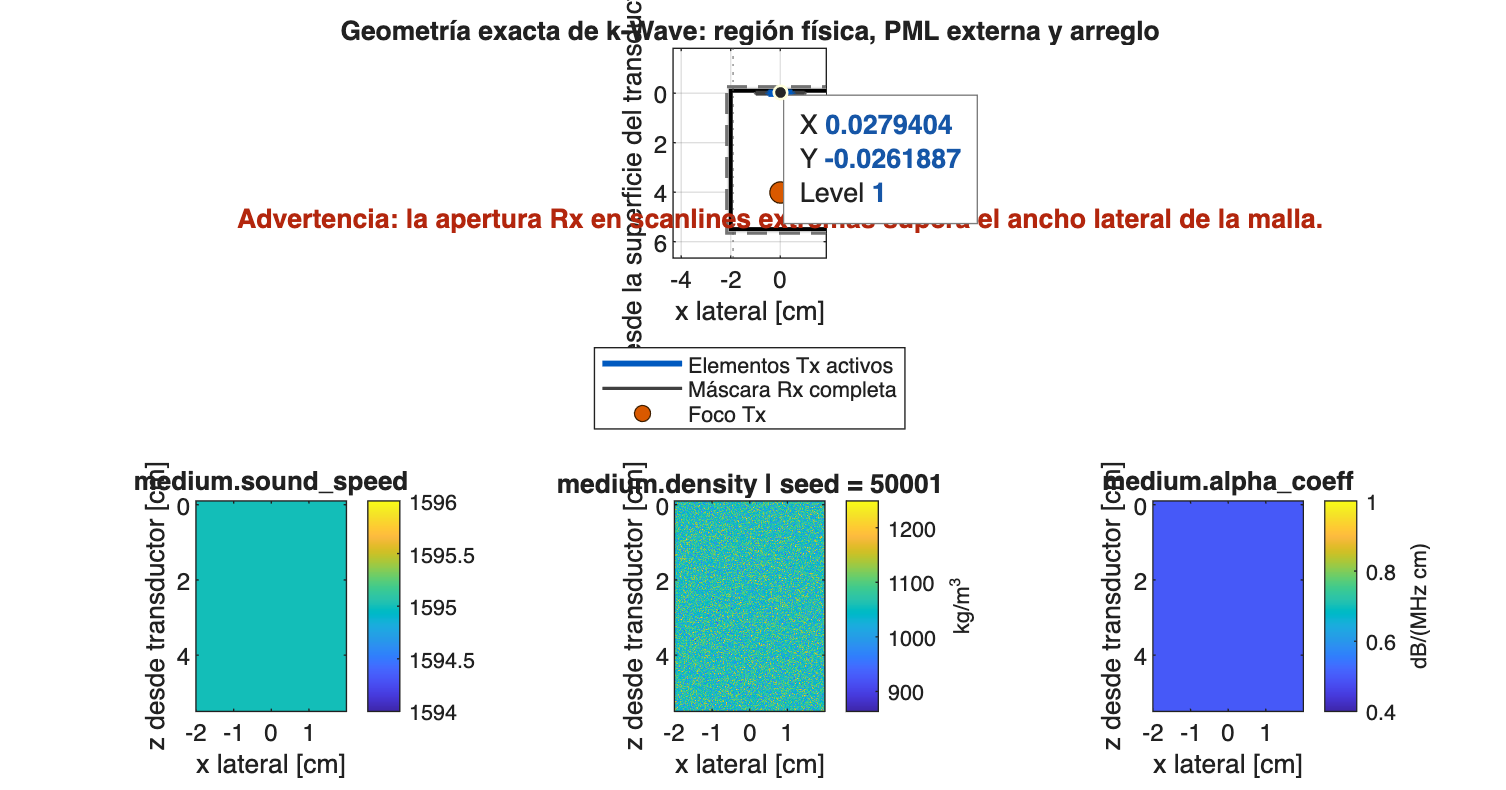

        % Axes and metadata
        fs = 1 / kgrid.dt;
    
        offset = 1;
    
        axAxis = 0:kgrid.Nt-1;
        axAxis = axAxis * kgrid.dt * c0 / 2;
    
        z = axAxis(offset:end);
        x = yCords;
    
        density_map = medium.density;
        alpha_coeff = medium.alpha_coeff;
        sound_speed = medium.sound_speed;
    
        outFile = fullfile(outputFolder, ...
            sprintf('rf_prebf_homRef_%03d.mat', iRef));
    
        save(outFile, ...
            'rf_prebf', ...
            'x', 'z', 'fs', 'time_delays', ...
            'density_map', 'alpha_coeff', 'sound_speed', ...
            'density_std', 'hom_alpha', ...
            'c0', 'rho0', ...
            'source_f0', 'source_amp', 'source_cycles', 'source_focus', ...
            'element_pitch', 'element_width', ...
            'focal_number_Tx', 'focal_number_Rx', ...
            'nLines', 'depth', ...
            'grid_size_x', 'grid_size_y', ...
            'dx', 'ppw', 'cfl', 'PMLSize', ...
            'refSeed', 'iRef', 'simuName', ...
            '-v7.3');

    
        manifest(iRef).file = outFile;

dx = 39.915 µm | Nx = 1402 | Ny = 1002


        manifest(iRef).seed = refSeed;
        manifest(iRef).density_std = density_std;

Elementos Rx = 66 | Elementos Tx activos = 33


        manifest(iRef).alpha_coeff = hom_alpha;

PML externa = 1.637 mm


    
    end

Foco = 40.0 mm desde la superficie del transductor


   
%Este archivo no guarda RF directamente.

Nx = 1402 | Ny = 1002 | dx = 39.915 µm\n

% Guarda información que permite identificar y reproducir las réplicas:
    save(fullfile(outputFolder, 'reference_manifest.mat'), ...

Elementos Rx = 66 | Elementos Tx activos = 33\n

        'manifest', 'nRefs', 'refSeedBase', 'density_std', 'hom_alpha');
    

Foco = 40.0 mm | PML externa = 1.64 mm\n

    fprintf('\nDone. Saved %d homogeneous reference files in:\n%s\n', ...
        nRefs, outputFolder);

end


**Funciones:**

%% Local helper function

function medium = makeHomogeneousDensityOnlyMedium(Nx, Ny, c0, rho0, densityStd, alpha)

    medium.sound_speed = c0 * ones(Nx, Ny);
    
    medium.density = rho0 .* (1 + densityStd * randn(Nx, Ny));
    
    medium.alpha_coeff = alpha * ones(Nx, Ny);

end

**Mejoras realizadas 3 setpiembre **

Se generaron los callbacks y funcionaldiad solo para generar .m y .mat, ademas se realizo lo siguiente:

- Se añadieron configuraciones avanzadas para medio, transductor, sensor, cálculo, reproducibilidad y salida.

- `Prueba` muestra en Ejecución la cola creada, incluyendo los valores objetivo y el valor de referencia.

- `Reset` elimina la referencia y las colas para iniciar otro experimento.

- `Open Config` recupera configuraciones guardadas.

- `Save` ahora genera automáticamente dos archivos en `apps/results`:

- Un `.mat` con toda la configuración, referencia y colas.

- Un `.m` reproducible basado en la estructura de `kWaveBaseCode.m`.

- El `.m` generado sí aplica cada valor de la cola a `hom_alpha` antes de crear el medio. Esto corrige el detalle del script de referencia, donde el nombre de la carpeta cambiaba, pero la atenuación podía quedarse fija.

- El pipeline generado considera 5 realizaciones aleatorias para cada objetivo y 10 para la referencia, usando semillas reproducibles.

- También guarda la configuración de malla, medio, transductor, sensor, cálculo y salida dentro del pipeline generado.

**Mejoras realizadas, 7 de septiembre **

- Se creó `PreviewLogic.m` como lógica separada de la GUI y de `QUSConfigurationLogic`.

- Se añadieron las pestañas Geometric, Properties y Signal.

- Geometric muestra dominio 2D, PML, emisor, elementos activos, foco y dominio del medio separado.

- Properties muestra velocidad de sonido, densidad y absorción con ejes `x`, `z` y unidades en cm.

- Signal muestra Tone Burst en tiempo y su espectro unilateral mediante FFT.

- La geometría y la señal se actualizan al pulsar Set.

- Save conserva el `.mat` para Open Config, pero genera un `.m` autónomo para cluster.

- El `.m` escribe los valores físicos directamente y no requiere `load(...)`.

- Para colas de atenuación, el `.m` escribe `refValues` y usa `hom_alpha = refValues(ii)`.

- La referencia queda al final y recibe el número de realizaciones de referencia; los demás valores usan el número de realizaciones normal.

- Para colas con más de un parámetro, el script expande las combinaciones como casos directos.

%% Figura exacta del setup k-Wave: hígado, PML, emisor y sensor

% =========================================================================
% Valores físicos: tejido hepático
% =========================================================================
c0 = 1595;              % velocidad del sonido [m/s]
rho0 = 1060;            % densidad media [kg/m^3]
hom_alpha = 0.50;       % atenuación [dB/(MHz cm)]
density_std = 0.04;     % variación relativa de densidad

% =========================================================================
% Fuente y transductor
% =========================================================================
source_f0 = 6.66e6;     % frecuencia [Hz]
source_amp = 1e6;       % presión [Pa]
source_cycles = 3.5;    % ciclos

source_focus = 4e-2;    % foco [m]
element_pitch = 0.3e-3; % pitch [m]
element_width = 0.25e-3;
focal_number_Tx = 4;
focal_number_Rx = 2;
nLines = 128;

% Coordenada interna de k-Wave: [axial, lateral].
base_translation = [-2.7e-2, 0];
rotation = 0;

% =========================================================================
% Malla y PML
% =========================================================================
grid_size_x = 5.6e-2;   % axial [m]
grid_size_y = 4e-2;     % lateral [m]
ppw = 6;
PMLSize = [41, 41];

dx = c0 / (ppw * source_f0);

Nx = roundEven(grid_size_x / dx);
Ny = roundEven(grid_size_y / dx);

% Esta es exactamente la malla usada por el pipeline.
kgrid = kWaveGrid(Nx, dx, Ny, dx);

% La PML se agrega fuera porque PMLInside = false.
pmlAxial = PMLSize(1) * dx;
pmlLateral = PMLSize(2) * dx;

% =========================================================================
% Medio: misma primera realización del pipeline
% =========================================================================
refSeedBase = 50000;
iRef = 1;
rng(refSeedBase + iRef);

medium.sound_speed = c0 * ones(Nx, Ny);
medium.density = rho0 .* (1 + density_std * randn(Nx, Ny));
medium.alpha_coeff = hom_alpha * ones(Nx, Ny);
medium.alpha_power = 1;
medium.alpha_mode = 'no_dispersion';
medium.sound_speed_ref = c0;

% =========================================================================
% Arreglo: misma geometría que el pipeline
% =========================================================================
apertureRx = source_focus / focal_number_Rx;
apertureTx = source_focus / focal_number_Tx;

elementNumRx = floor(apertureRx / element_pitch);
elementNumTx = floor(apertureTx / element_pitch);

elementIndices = (0:elementNumRx - 1) - (elementNumRx - 1) / 2;
activeMask = abs(elementIndices) <= (elementNumTx - 1) / 2;

% Arreglo completo: funciona como sensor receptor.
receiverArray = kWaveArray( ...
    'BLITolerance', 0.05, ...
    'UpsamplingRate', 10);

% Arreglo activo: solo elementos que transmiten.
transmitterArray = kWaveArray( ...
    'BLITolerance', 0.05, ...
    'UpsamplingRate', 10);

for index = 1:elementNumRx
    yPos = elementIndices(index) * element_pitch;

    receiverArray.addRectElement( ...
        [0, yPos], element_width / 4, element_width, rotation);

    if activeMask(index)
        transmitterArray.addRectElement( ...
            [0, yPos], element_width / 4, element_width, rotation);
    end
end

% Scanline central: la primera figura muestra la geometría de referencia.
receiverArray.setArrayPosition(base_translation, rotation);
transmitterArray.setArrayPosition(base_translation, rotation);

% Máscaras discretizadas exactamente sobre kgrid.
receiverMask = receiverArray.getArrayBinaryMask(kgrid);
transmitterMask = transmitterArray.getArrayBinaryMask(kgrid);

% Coordenadas reales de k-Wave.
xCm = kgrid.y(1, :) * 100;
zCm = (kgrid.x(:, 1) - base_translation(1)) * 100;

% Límites de la región física y de la PML externa.
xMin = min(xCm);
xMax = max(xCm);
zMin = min(zCm);
zMax = max(zCm);

pmlAxialCm = pmlAxial * 100;
pmlLateralCm = pmlLateral * 100;

% =========================================================================
% Verificación de cobertura lateral para scanlines extremas
% =========================================================================
scanCenters = ((0:nLines - 1) - (nLines - 1) / 2) * element_pitch;

halfReceiverAperture = elementNumRx * element_pitch / 2;
requiredHalfWidth = max(abs(scanCenters)) + halfReceiverAperture;
availableHalfWidth = (max(kgrid.y(:)) - min(kgrid.y(:))) / 2;

isReceiverClippedAtEdges = requiredHalfWidth > availableHalfWidth;

% =========================================================================
% Figura
% =========================================================================
figure('Color', 'w', 'Position', [100 100 1450 760]);
tiledlayout(2, 3, 'TileSpacing', 'compact', 'Padding', 'compact');

%% Geometría exacta
nexttile([1 3]);
hold on;
axis equal;
box on;
grid on;

% PML externa: no pertenece a la región física definida por kgrid.
rectangle('Position', [ ...
    xMin - pmlLateralCm, ...
    zMin - pmlAxialCm, ...
    (xMax - xMin) + 2 * pmlLateralCm, ...
    (zMax - zMin) + 2 * pmlAxialCm], ...
    'FaceColor', [0.92 0.92 0.92], ...
    'EdgeColor', [0.45 0.45 0.45], ...
    'LineStyle', '--', ...
    'LineWidth', 1.2);

% Región física donde están el medio, fuente y sensor.
rectangle('Position', [ ...
    xMin, zMin, xMax - xMin, zMax - zMin], ...
    'FaceColor', 'w', ...
    'EdgeColor', 'k', ...
    'LineWidth', 1.5);

% Máscara del receptor: gris.
contour(xCm, zCm, receiverMask, [0.5 0.5], ...
    'Color', [0.25 0.25 0.25], ...
    'LineWidth', 1.2);

% Máscara activa de transmisión: azul.
contour(xCm, zCm, transmitterMask, [0.5 0.5], ...
    'Color', [0.00 0.35 0.75], ...
    'LineWidth', 2.2);

% El foco se expresa respecto a la superficie del transductor.
plot(0, source_focus * 100, 'o', ...
    'MarkerSize', 8, ...
    'MarkerFaceColor', [0.85 0.35 0], ...
    'MarkerEdgeColor', [0.25 0.12 0]);

% Rango de centros de las scanlines.
xline(min(scanCenters) * 100, ':', 'Color', [0.35 0.35 0.35]);
xline(max(scanCenters) * 100, ':', 'Color', [0.35 0.35 0.35]);

xlabel('x lateral [cm]');
ylabel('z desde la superficie del transductor [cm]');
title('Geometría exacta de k-Wave: región física, PML externa y arreglo');
set(gca, 'YDir', 'reverse');

transmitterLegend = plot(nan, nan, '-', ...
    'Color', [0.00 0.35 0.75], 'LineWidth', 2.2);
receiverLegend = plot(nan, nan, '-', ...
    'Color', [0.25 0.25 0.25], 'LineWidth', 1.2);
focusLegend = plot(nan, nan, 'o', ...
    'MarkerFaceColor', [0.85 0.35 0], ...
    'MarkerEdgeColor', [0.25 0.12 0]);

legend([transmitterLegend receiverLegend focusLegend], ...
    {'Elementos Tx activos', 'Máscara Rx completa', 'Foco Tx'}, ...
    'Location', 'southoutside');

if isReceiverClippedAtEdges
    text(0, zMax + pmlAxialCm, ...
        sprintf(['Advertencia: la apertura Rx en scanlines extremas ' ...
        'supera el ancho lateral de la malla.']), ...
        'HorizontalAlignment', 'center', ...
        'VerticalAlignment', 'bottom', ...
        'Color', [0.70 0.15 0.05], ...
        'FontWeight', 'bold');
end

hold off;

%% Velocidad de sonido: matriz exacta enviada a k-Wave
nexttile;
imagesc(xCm, zCm, medium.sound_speed);
axis image;
set(gca, 'YDir', 'reverse');
colorbar;
xlabel('x lateral [cm]');
ylabel('z desde transductor [cm]');
title('medium.sound\_speed');

%% Densidad: primera realización exacta
nexttile;
imagesc(xCm, zCm, medium.density);
axis image;
set(gca, 'YDir', 'reverse');
densityColorbar = colorbar;
ylabel(densityColorbar, 'kg/m^3');
xlabel('x lateral [cm]');
ylabel('z desde transductor [cm]');
title(sprintf('medium.density | seed = %d', refSeedBase + iRef));

%% Atenuación: matriz exacta enviada a k-Wave
nexttile;
imagesc(xCm, zCm, medium.alpha_coeff);
axis image;
set(gca, 'YDir', 'reverse');
clim([0.4 1.0]);
absorptionColorbar = colorbar;
ylabel(absorptionColorbar, 'dB/(MHz cm)');
xlabel('x lateral [cm]');
ylabel('z desde transductor [cm]');
title('medium.alpha\_coeff');

fprintf('dx = %.3f µm | Nx = %d | Ny = %d\n', dx * 1e6, Nx, Ny);
fprintf('Elementos Rx = %d | Elementos Tx activos = %d\n', ...
    elementNumRx, elementNumTx);
fprintf('PML externa = %.3f mm\n', pmlAxial * 1e3);
fprintf('Foco = %.1f mm desde la superficie del transductor\n', ...
    source_focus * 1e3);

fprintf('Nx = %d | Ny = %d | dx = %.3f µm\\n', Nx, Ny, dx * 1e6);
fprintf('Elementos Rx = %d | Elementos Tx activos = %d\\n', ...
    elementNumRx, elementNumTx);
fprintf('Foco = %.1f mm | PML externa = %.2f mm\\n', ...
    source_focus * 1e3, pmlThickness * 1e3);
